clear
syms y t
f = @(t,y) (-t./(y+t));
[t,y] = meshgrid(-4:0.3:6,-4:0.3:6);
u = ones(length(t));
v = f(t,y);
l = sqrt(u.*u + v.*v);
quiver(t, y, u./l, v./l)
grid on
t0 = [-1 6]

t0 =     -1     6


y0 = [2:0.4:4]

y0 =    2.000000000000000   2.400000000000000   2.800000000000000   3.200000000000000   3.600000000000000   4.000000000000000


[t,y] = ode45(f,t0,y0)

t =   -1.000000000000000
  -0.899524542739617
  -0.799049085479234
  -0.698573628218850
  -0.598098170958467
  -0.423098170958467
  -0.248098170958467
  -0.073098170958467
   0.101901829041533
   0.276901829041533


y =    2.000000000000000   2.400000000000000   2.800000000000000   3.200000000000000   3.600000000000000   4.000000000000000
   2.087628408533719   2.464493742929207   2.850931666094831   3.242046715219551   3.635785812897752   4.031140366885548
   2.154705897610396   2.516513887370951   2.893141492420586   3.277465128549787   3.666256053184322   4.057856846754605
   2.207158540232560   2.558583696147092   2.927961122870133   3.307059525866394   3.691942678729546   4.080524752419988
   2.248527484080209   2.592440216170730   2.956389276532339   3.331467389305152   3.713283694821979   4.099461779006258
   2.299494140228420   2.635104047731420   2.992769776012969   3.363048142937258   3.741122029109587   4.124318681289981
   2.329248996034645   2.660569932350167   3.014835673603908   3.382430110677526   3.758360555220054   4.139818489396855
   2.342201424573233   2.671827315949266   3.024704211714794   3.391175726112591   3.766193158867977   4.146900154916707
   2.341257573331631   2.670

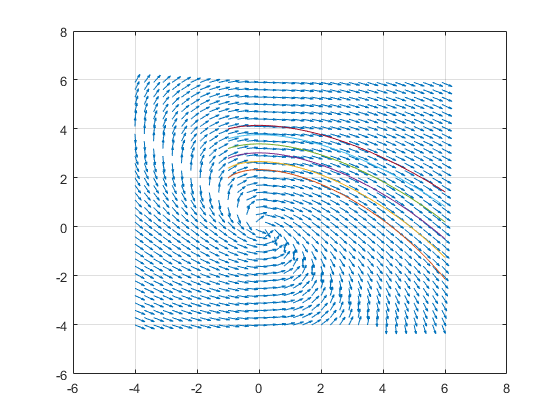

hold on
plot(t,y)
hold off